# Sistemas de Control II - FCEFyN (UNC)

## Caso de estudio 2 - Motor (Actividad 1.5)

clear all; close all; clc;

data= readtable('../Resources/Curvas_Medidas_Motor_2025_v.xls');
data;
% Convert table to array. Apply transpose.
dataT= table2array(data);

% Obtain time(t).
t      = dataT(:,1);
wr     = dataT(:,2);
ia     = dataT(:,3);
v      = dataT(:,4);
torque = dataT(:,5);

Plot measurements

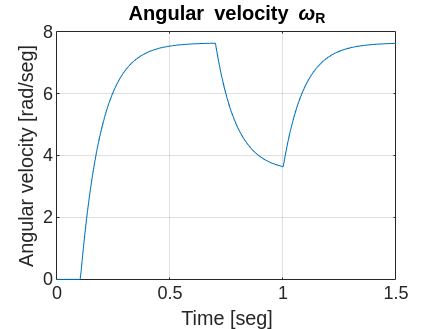

figure(1); plot(t, wr); title('Angular velocity \omega_{R}'); 
ylabel('Angular velocity [rad/seg]'); xlabel('Time [seg]');
grid on; %xlim([0, 0.7]);

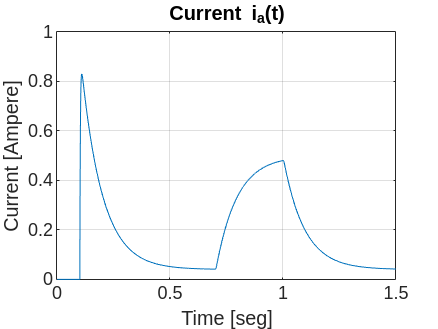

figure(2); plot(t, ia); title('Current i_{a}(t)'); 
ylabel('Current [Ampere]'); xlabel('Time [seg]');
grid on;

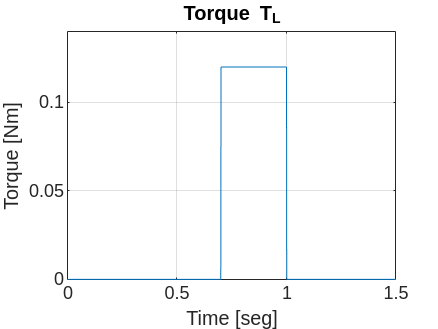

figure(3); plot(t, torque); title('Torque T_{L}'); 
ylabel('Torque [Nm]'); xlabel('Time [seg]');
grid on; ylim([0, 0.14]);

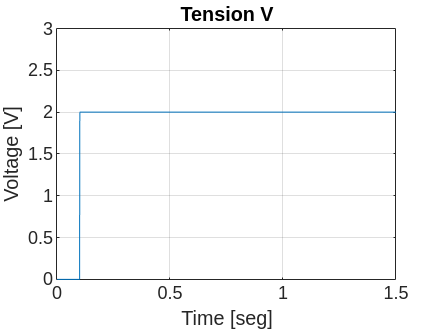

figure(4); plot(t, v); title('Tension V'); 
ylabel('Voltage [V]'); xlabel('Time [seg]');
grid on; ylim([0, 3])

Apply Chen Method to $$ Angular \, velocity \, (\omega_{R}) $$

Transfer Function $$ \frac{ \omega_{R} }{ V_{a} } = \frac{\mathrm{Ki}}{J\,\mathrm{Laa}\,\left(s^2+\frac{\mathrm{Laa}\,\left(\mathrm{Bm}\,\mathrm{Ra}+\mathrm{Ki}\,\mathrm{Km}\right)}{J}+\frac{s\,\left(\mathrm{Bm}\,\mathrm{Laa}+J\,\mathrm{Ra}\right)}{J}\right)} $  $

K= max(wr)

K = 7.6247

stepAmplitude= max(v)

stepAmplitude = 2


tc      = dataT(101:end,1);
wrc     = dataT(101:end,2);
%ia     = dataT(:,3);
%v      = dataT(:,4);
%torque = dataT(:,5);

i  = 35;
t1 = tc(i);
y1 = wrc(i)

y1 = 2.2034

t2 = tc(2*i);
y2 = wrc(2*i)

y2 = 3.9158

t3 = tc(3*i);
y3 = wrc(3*i)

y3 = 5.0885


delayTime= 0.101;

TF= minreal(chenMethod(y1, y2, y3, K, stepAmplitude, delayTime, t1, 2));

K = 3.8124

T1_e = 0.0071

T2_e = 0.0895

disp('Transfer Function: ')

Transfer Function: 


TF


TF =
 
          5981
  --------------------
  s^2 + 151.5 s + 1569
 
Continuous-time transfer function.
Model Properties


disp('Poles and zeros: ')

Poles and zeros: 


pole(TF)

ans =  -140.3422
  -11.1785


zero(TF)


ans =

  0×1 empty double column vector



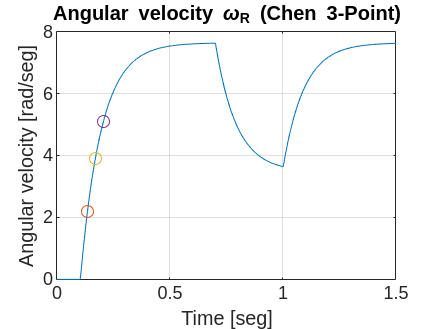


figure(4);
plot(t, wr); title('Angular velocity \omega_{R} (Chen 3-Point)'); 
ylabel('Angular velocity [rad/seg]'); xlabel('Time [seg]'); grid on; hold on;
plot(t1, y1, 'o'); hold on;
plot(t2, y2, 'o'); hold on;
plot(t3, y3, 'o'); hold on;

Approximation plotting

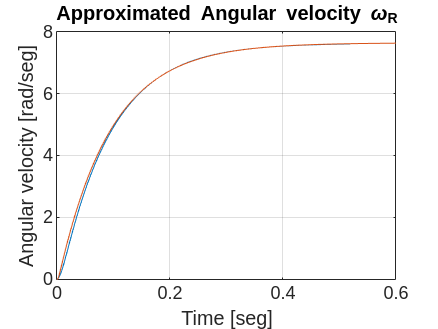


[ys, ts]= step(TF);
figure(5);
ys= ys*stepAmplitude;
plot(ts, ys); title('Approximated Angular velocity \omega_{R}'); 
ylabel('Angular velocity [rad/seg]'); xlabel('Time [seg]'); grid on;
xlim([0, 0.6]); hold on;
plot(t-delayTime, wr)

Apply Chen Method to $$ Torque \, (T_{L}) $$

Transfer Function $$ \frac{ \omega_{R} }{ T_{L}} = -\frac{\frac{s}{J}+\frac{\mathrm{Ra}}{J\,\mathrm{Laa}}}{s^2+\frac{\mathrm{Bm}\,\mathrm{Ra}+\mathrm{Ki}\,\mathrm{Km}}{J\,\mathrm{Laa}}+\frac{s\,\left(\mathrm{Bm}\,\mathrm{Laa}+J\,\mathrm{Ra}\right)}{J\,\mathrm{Laa}}}$$

t_tl = t(701:end, 1);
%size(t(701:end, 1))
%size(t, 1)
wr_tl= wr(701:end, 1);
min(wr_tl)

ans = 3.6380

max(wr_tl)

ans = 7.6247

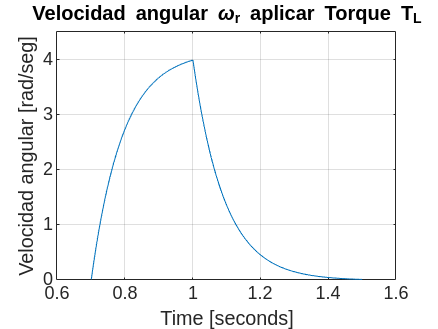

for i=1: length(t_tl)
    wr_tl(i)= (wr_tl(i)-max(wr_tl))*(-1);
end

%% Generate .csv to new data [t_tl, wr_tl]. 
filename= 'Generated Data/dataTL.csv';
headers= {'Time [Seconds]', 'Torque [Nm]'};
fi= fopen(filename, 'w');
fprintf(fi, '%s,%s\n', headers{:});
fclose(fi);
writematrix([t_tl, wr_tl], filename, 'WriteMode', 'append');

figure(6)
plot(t_tl, wr_tl);
ylim([0, 4.5]); grid on; title('Velocidad angular \omega_{r} aplicar Torque T_{L}');
xlabel('Time [seconds]'); ylabel('Velocidad angular [rad/seg]');


% Apply Chen's method (Second-Order Systems with differents poles).